# **Case Study: Condition Monitoring and Prognostics Using Bearing Vibration Signals**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

This case study a slight modification of a tutorial by Mathworks. 

This example shows how to extract features from vibration signals from a ball bearing, conduct health monitoring, and perform prognostics. 

Needs:

-  Signal Processing Toolbox

-  System Identification Toolbox

## Data Description

**Dowload Dataset**

Mathworks Ball Bearing Dataset '`pdmBearingConditionMonitoringData.mat' `

[Download link](https://www.mathworks.com/supportfiles/predmaint/condition-monitoring-and-prognostics-using-vibration-signals/pdmBearingConditionMonitoringData.mat)

Save the data file under the directory of `/IAIA/Dataset/`

The data is stored in a cell array, which was generated using a ball bearing signal simulator with single point defect on the **outer race** of the bearing. 

- It contains multiple segments of vibration signals for bearings simulated in different health conditions

- Defect depth increases from 3um to above 3mm 

- Each segment stores signals collected for 1 second at a sampling rate of 20 kHz. 

In pdmBearingConditionMonitoring`Data.mat`, 

- `defectDepthVec` : stores how defect depth changes versus time

- `expTime` : stores the corresponding time in minutes.

%%% Download dataset from website
% url = 'https://www.mathworks.com/supportfiles/predmaint/condition-monitoring-and-prognostics-using-vibration-signals/pdmBearingConditionMonitoringData.mat';
% websave('pdmBearingConditionMonitoringData.mat',url);

load ('../../Dataset/pdmBearingConditionMonitoringData.mat')

% Define the number of data points to be processed.
numSamples = length(data);

% Define sampling frequency.
fs = 20E3;          % unit: Hz

Plot how defect depth changes in different segments of data.

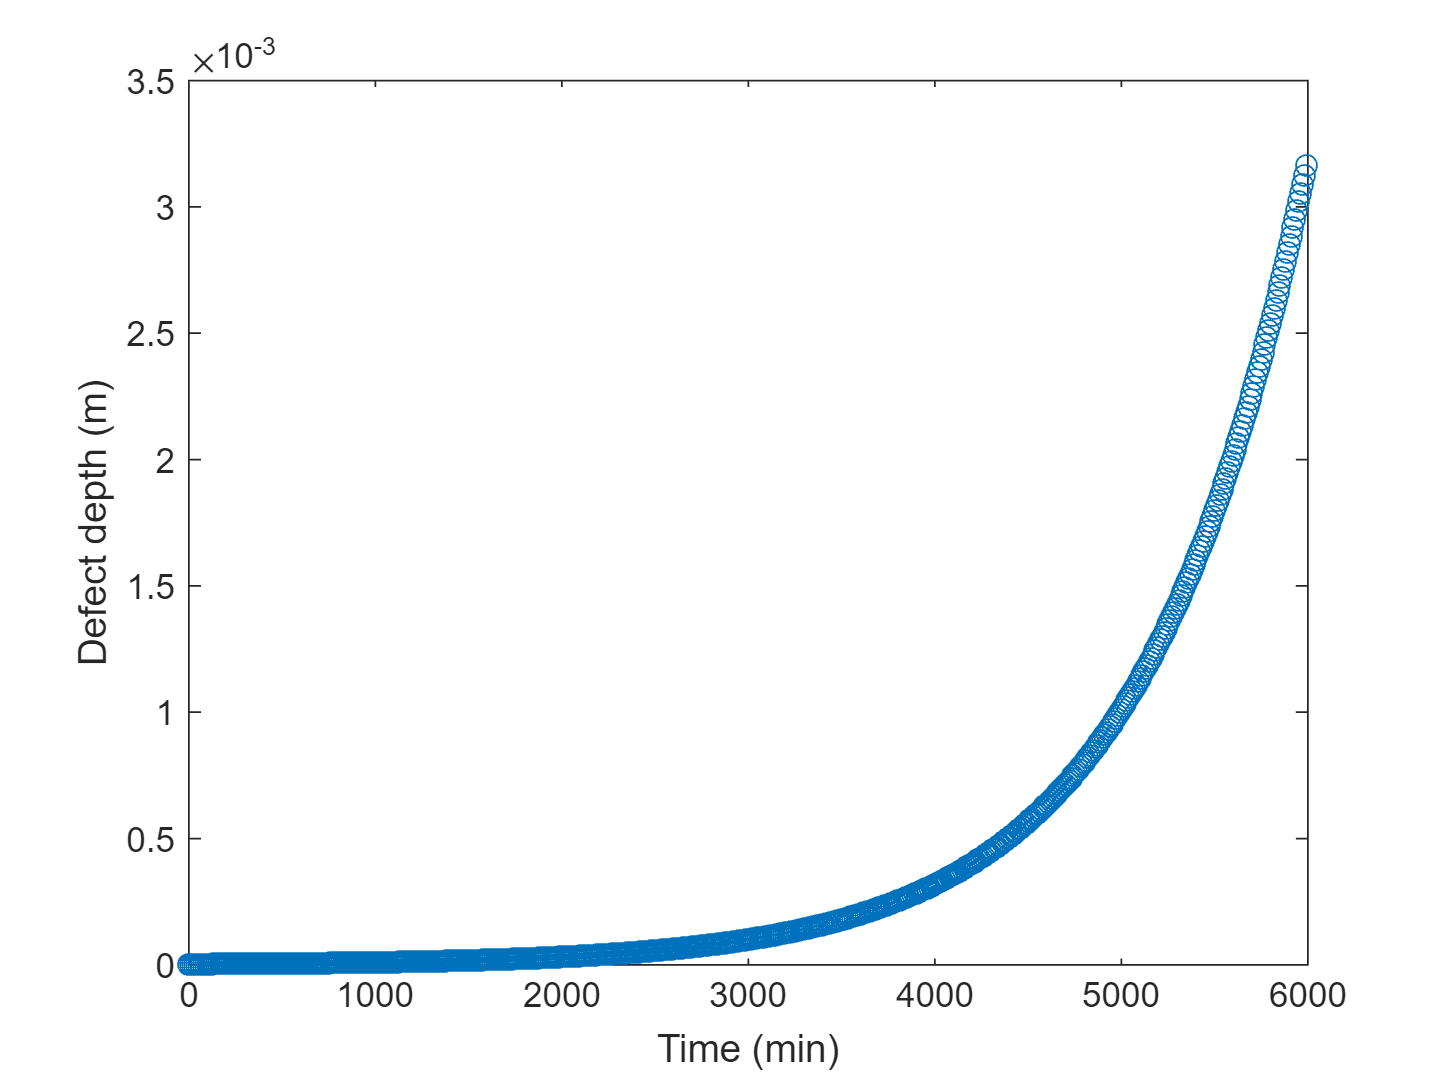

plot(expTime,defectDepthVec, 'o');
xlabel('Time (min)');
ylabel('Defect depth (m)');

Plot the healthy and faulty data.

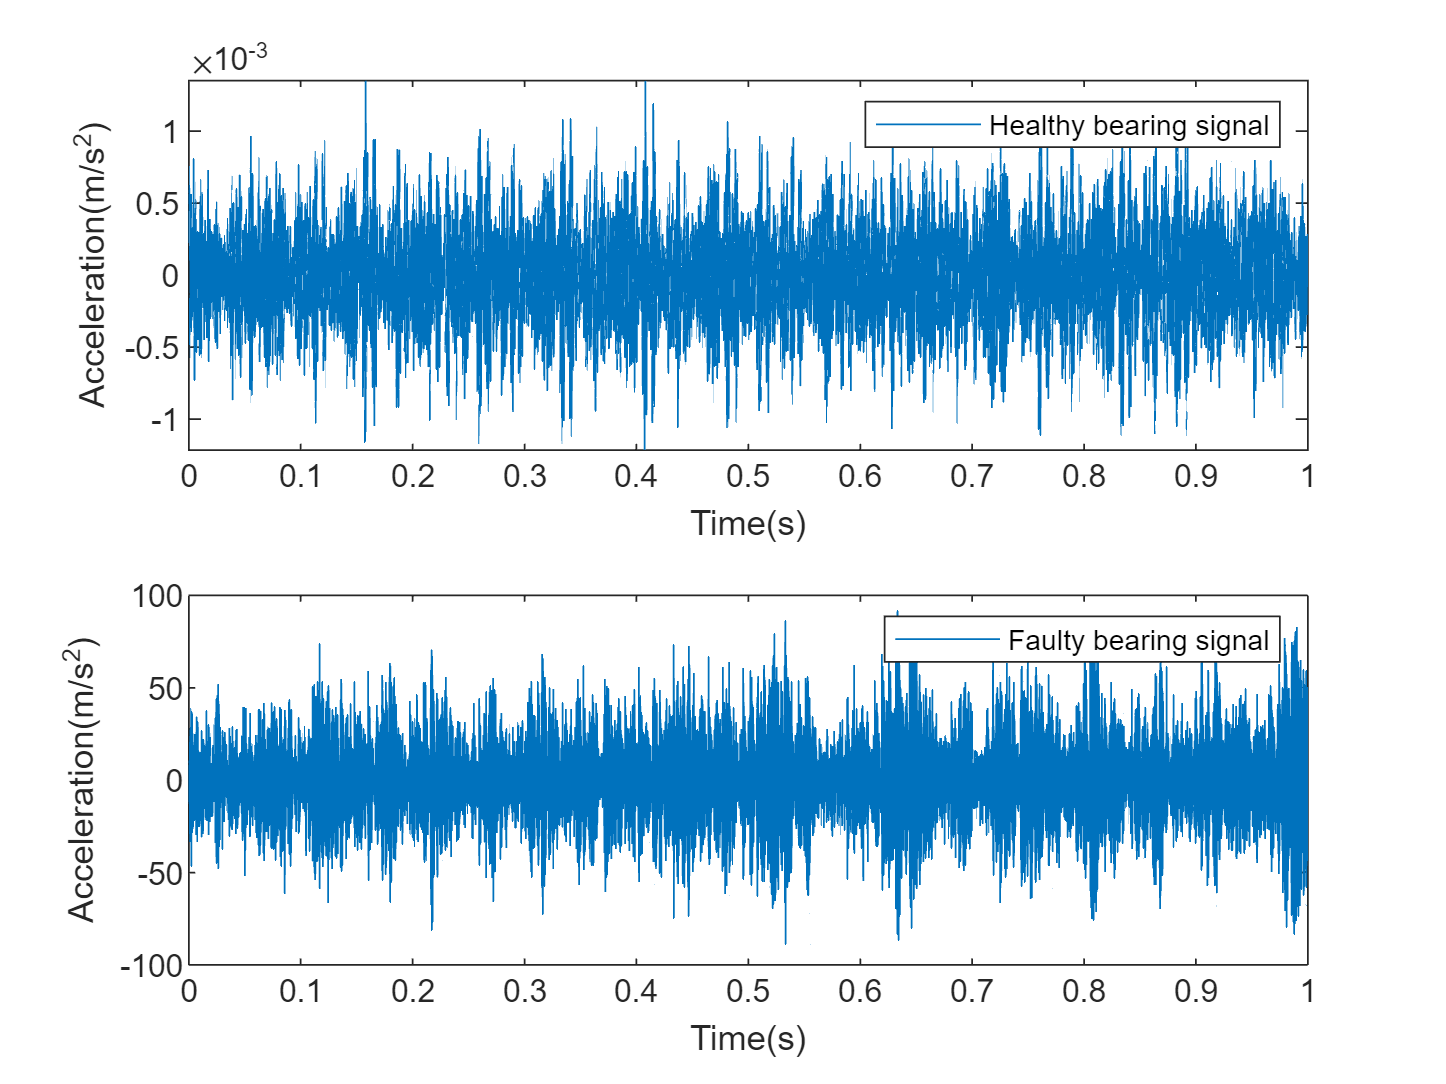

time = linspace(0,1,fs)';

% healthy bearing signal
subplot(2,1,1);
plot(time,data{1});
xlabel('Time(s)');
ylabel('Acceleration(m/s^2)');
legend('Healthy bearing signal');

% faulty bearing signal
subplot(2,1,2);
plot(time,data{end});
xlabel('Time(s)');
ylabel('Acceleration(m/s^2)');
legend('Faulty bearing signal');

## Feature Extraction

In this section, representative features are extracted from each segment of data. 

Typical features for bearing diagnostics and prognostics include 

- time-domain features (root mean square, peak value, signal kurtosis, etc.)

-  or frequency-domain features (peak frequency, mean frequency, etc.).

Before selecting which features to use, **plot the vibration signals spectrogram**. 

Visualizing signals in time-domain or frequency-domain or time-frequency domain can help discover signal patterns that indicate degradation or failure.

First calculate the spectrogram of the healthy bearing data. 

- Use a window size of 500 data points and an overlap ratio of 90% (equivalent to 450 data points). 

- Set the number of points for the FFT to be 512. 

- `fs` represents the sampling frequency defined previously.

[~,fvec,tvec,P0] = spectrogram(data{1},500,450,512,fs);

`P0` is the spectrogram, `fvec` is the frequency vector and `tvec` is the time vector.

Plot the spectrogram of the **healthy bearing signal.**

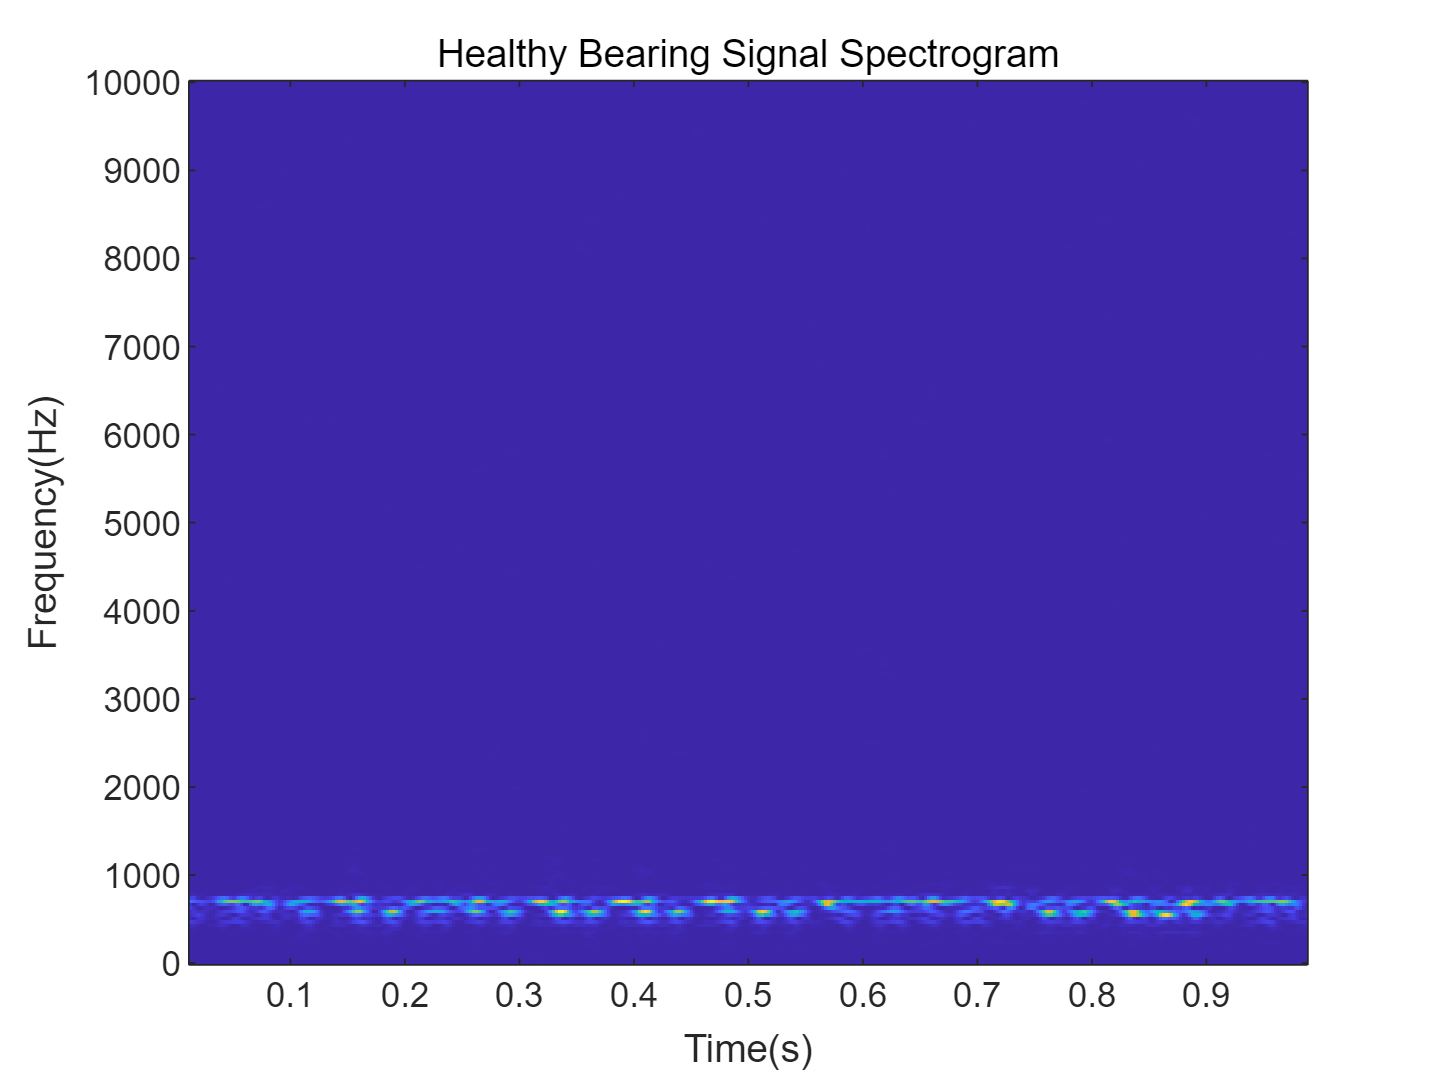

clf;
imagesc(tvec,fvec,P0)
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Healthy Bearing Signal Spectrogram');
axis xy

Now plot the spectrogram of vibration signals that have **developed faulty patterns. **

You can see that signal energies are concentrated at higher frequencies.

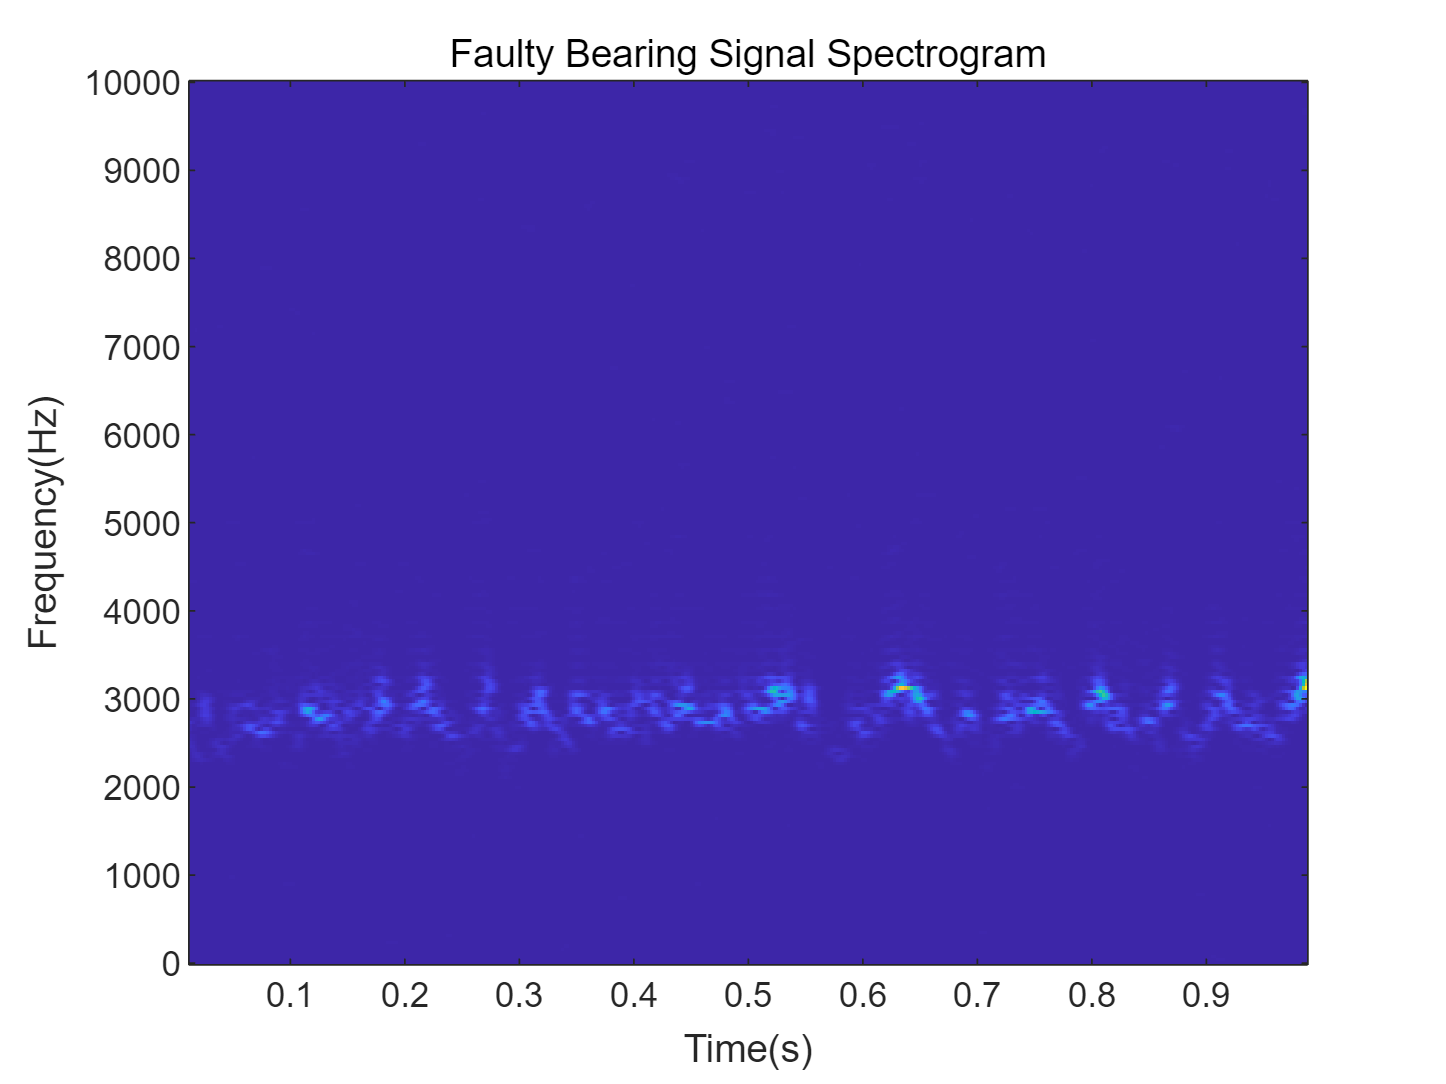

[~,fvec,tvec,Pfinal] = spectrogram(data{end},500,450,512,fs);
imagesc(tvec,fvec,Pfinal)
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Faulty Bearing Signal Spectrogram');
axis xy

Since the spectrograms for data from healthy and faulty bearings are different, representative features can be extracted from spectrograms and used for condition monitoring and prognostics. 

In this example, extract** mean peak frequencies** from spectrograms as health indicators. 

Denote the spectrogram as $P(t,\omega)$. Peak frequency at each time instance is defined as:


$$PeakFreq(t) = argmax_{\omega} P(t,\omega)$$


The mean peak frequency is the average of peak frequencies defined above.


$$meanPeakFreq = \frac{1}{T}\int_{0}^{T}{PeakFreq(t)dt}$$


Calculate the mean peak frequency for healthy ball bearing signals.

[~,I0] = max(P0);               % Find out where the peak frequencies are located.
meanPeakFreq0 = mean(fvec(I0))  % Calculate mean peak frequency.

meanPeakFreq0 = 666.4602

The healthy bearing vibration signals have mean peak frequency at around 650 Hz. 

Now calculate the mean peak frequency for faulty bearing signals. The mean peak frequency shifts to above 2500 Hz.

[~,Ifinal] = max(Pfinal);
meanPeakFreqFinal = mean(fvec(Ifinal))

meanPeakFreqFinal = 2.8068e+03

Examine the data at **middle stage, **when the defect depth is not very large but starting to affect the vibration signals. 

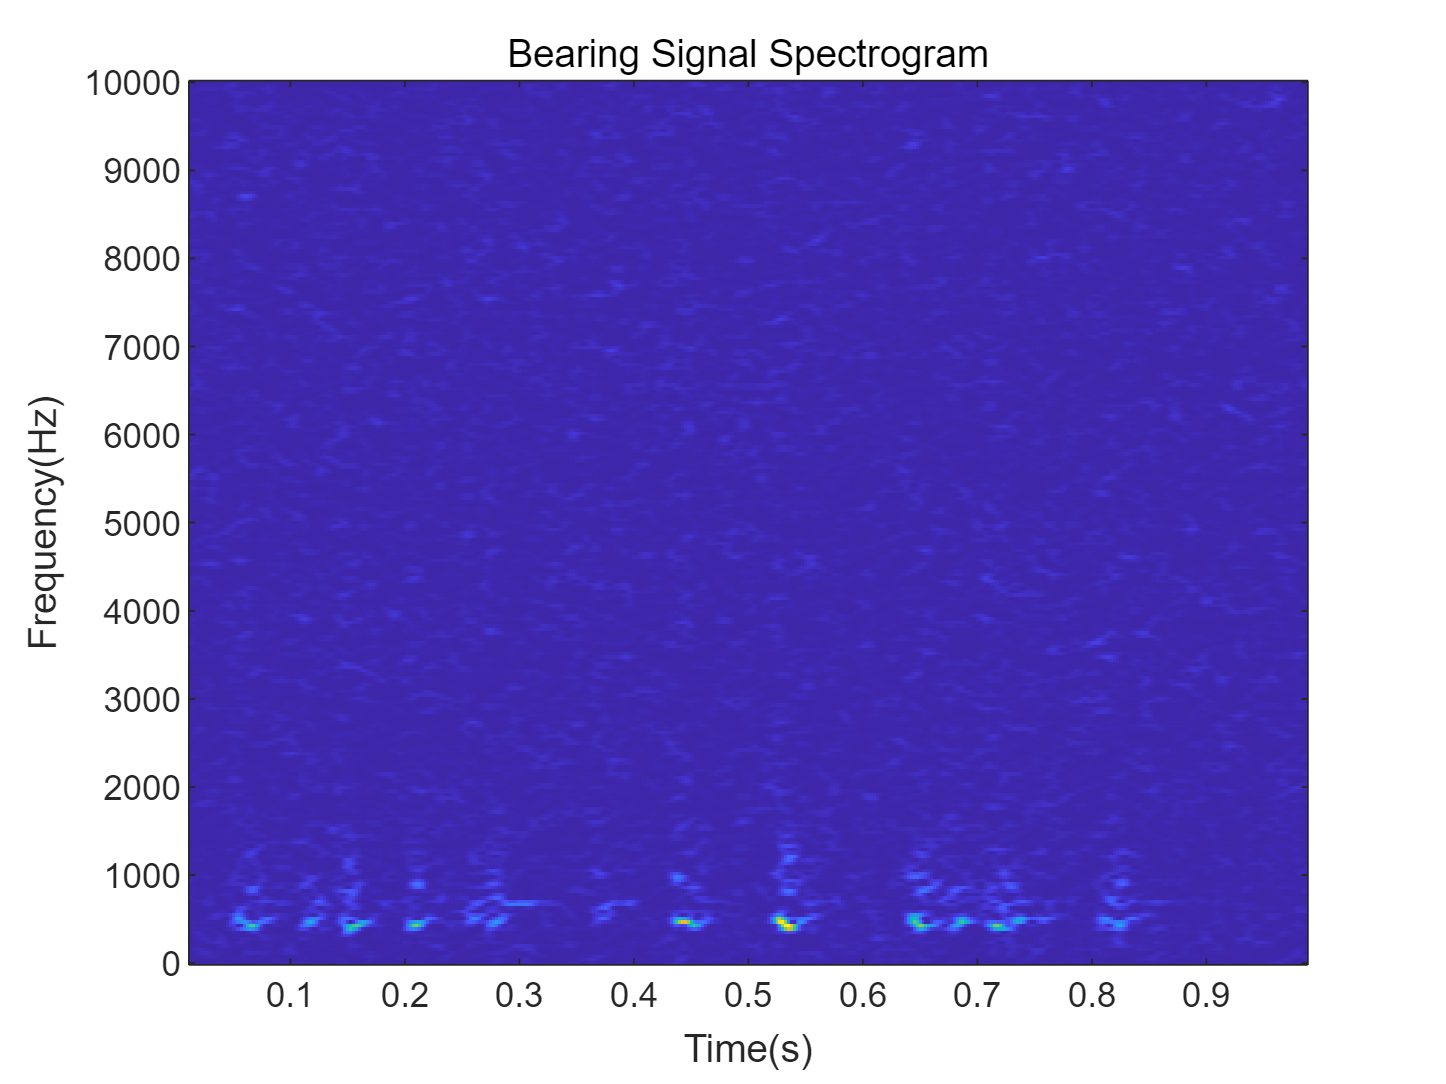

[~,fvec,tvec,Pmiddle] = spectrogram(data{end/2},500,450,512,fs);
imagesc(tvec,fvec,Pmiddle)
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Bearing Signal Spectrogram');
axis xy


[~,Imiddle] = max(Pmiddle);
meanPeakFreqFinal = mean(fvec(Imiddle))

meanPeakFreqFinal = 2.2514e+03

The high frequency noise components are spread all over the spectrogram. 

Such phenomena are mixed effects of both original vibrations and the vibrations induced by small defects. 

To accurately calculate mean peak frequency, filter the data to remove those high frequency components.

Apply a median filter to the vibration signals to remove high frequency noise components as well as to preserve useful information in the high frequencies.

dataMiddleFilt = medfilt1(data{end/2},3);

Plot spectrogram after **median filtering**. The high frequency components are suppressed.

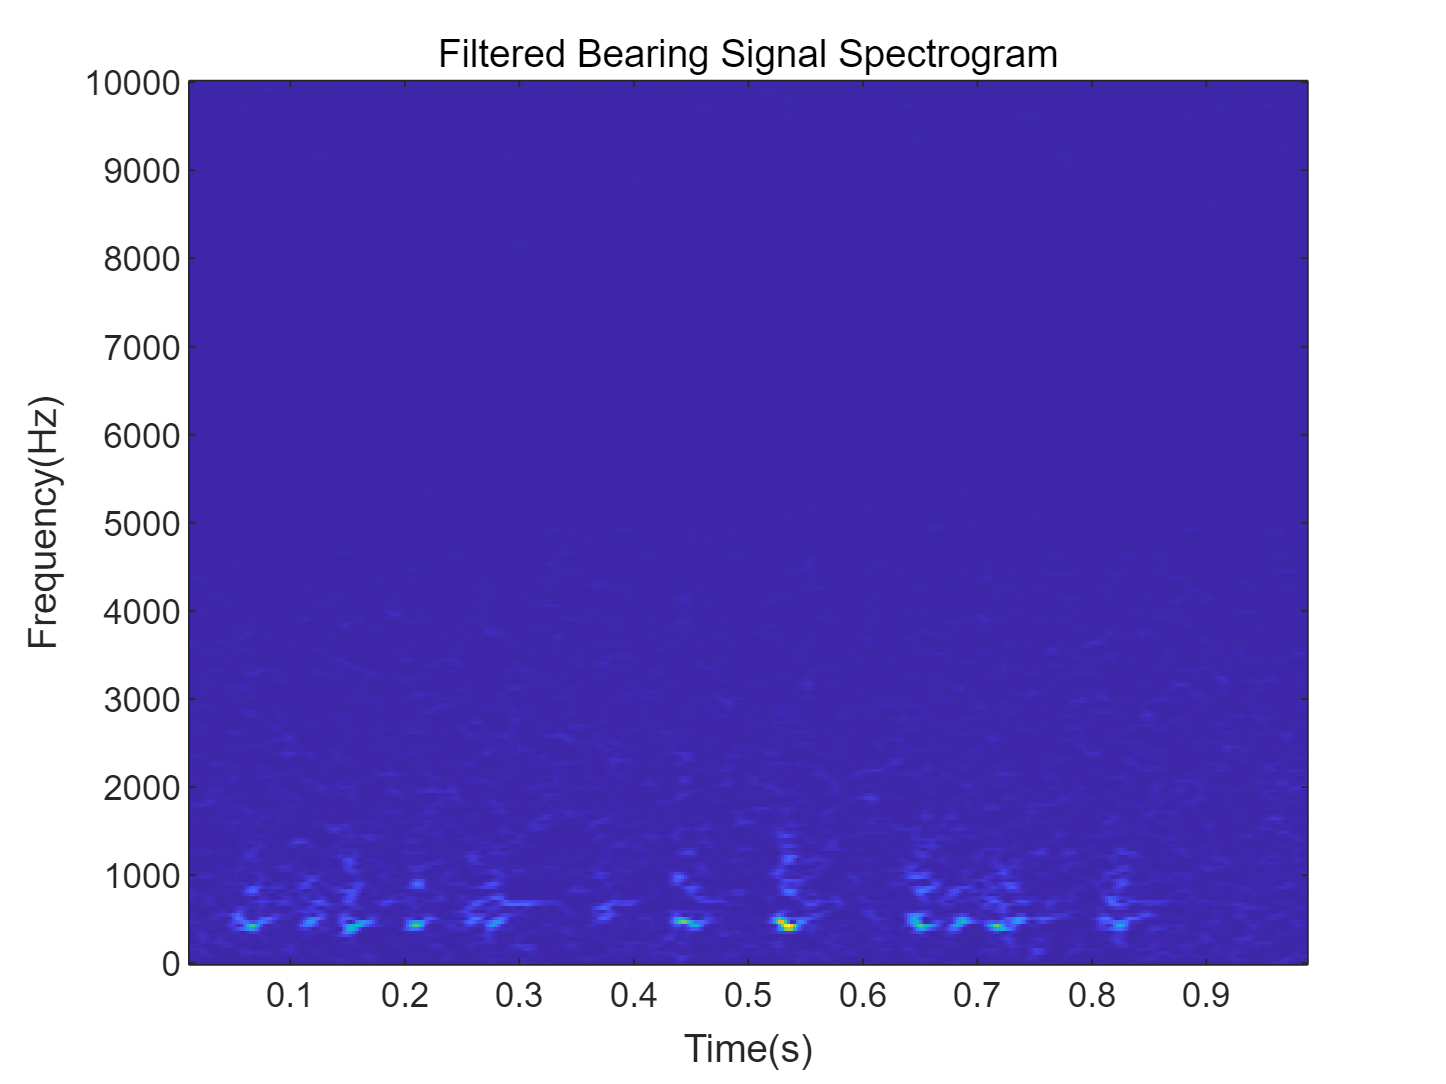

[~,fvec,tvec,Pmiddle] = spectrogram(dataMiddleFilt,500,450,512,fs);
imagesc(tvec,fvec,Pmiddle)
xlabel('Time(s)');
ylabel('Frequency(Hz)');
title('Filtered Bearing Signal Spectrogram');
axis xy

[~,Imiddle] = max(Pmiddle);
meanPeakFreqFinal = mean(fvec(Imiddle))

meanPeakFreqFinal = 802.5296

Since the mean peak frequency successfully distinguishes healthy ball bearings from faulty ball bearings, extract mean peak frequency from each segment of data.

% Define a progress bar.
h = waitbar(0,'Start to extract features');
% Initialize a vector to store the extracted mean peak frequencies.
meanPeakFreq = zeros(numSamples,1);
for k = 1:numSamples
    % Get most up-to-date data.
    curData = data{k};
    % Apply median filter.
    curDataFilt = medfilt1(curData,3);
    % Calculate spectrogram.
    [~,fvec,tvec,P_k] = spectrogram(curDataFilt,500,450,512,fs);
    % Calculate peak frequency at each time instance.
    [~,I] = max(P_k);
    meanPeakFreq(k) = mean(fvec(I));
    % Show progress bar indicating how many samples have been processed.
    waitbar(k/numSamples,h,'Extracting features');
end
close(h);

Plot the extracted mean peak frequencies versus time.

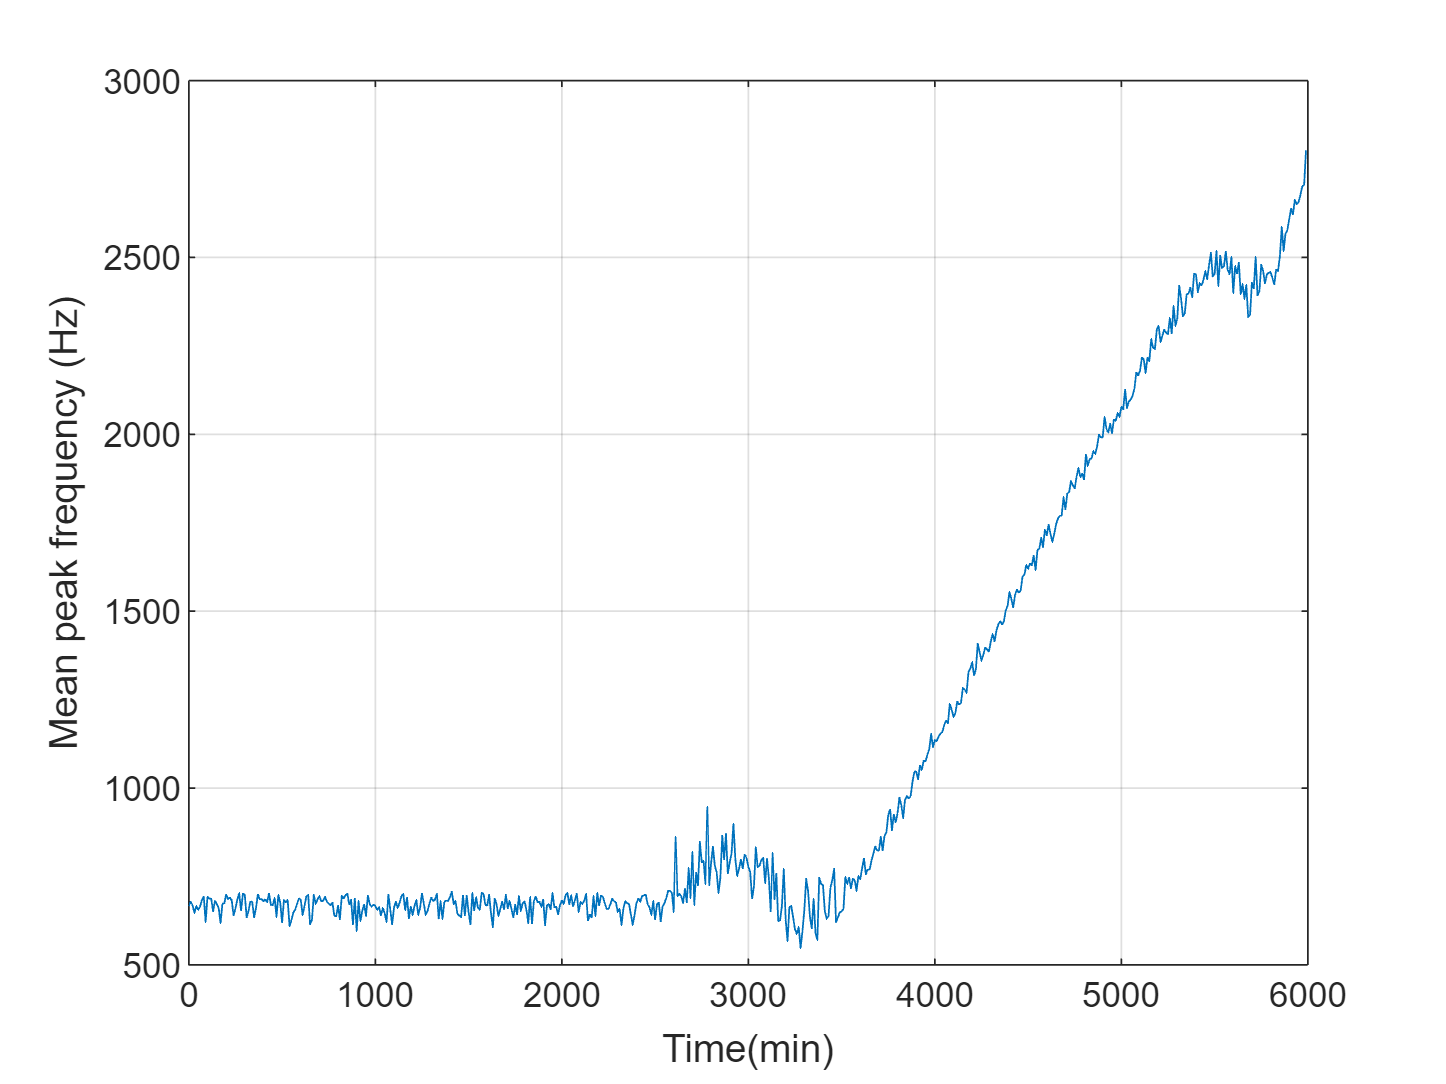

plot(expTime,meanPeakFreq);
xlabel('Time(min)');
ylabel('Mean peak frequency (Hz)');
grid on;

## Condition Monitoring and Prognostics

In this section, condition monitoring and prognostics are performed using a pre-defined threshold and dynamic models. For condition monitoring, create an alarm that triggers if the mean peak frequency exceeds the predefined threshold. For prognostics, identify a dynamic model to forecast the values of mean peak frequencies in the next few hours. Create an alarm that triggers if the forecast mean peak frequency exceeds the predefined threshold.

Forecasting helps us better prepare for a potential fault or even stop the machine before failure. Consider the mean peak frequency as a time series. We can estimate a time series model for the mean peak frequency and use the model to forecast the future values. Use the first 200 mean peak frequency values to create an initial time series model, then once 10 new values are available, use the last 100 values to update the time series model. This batch mode of updating the time series model captures instantaneous trends. The updated time series model is used to compute a 10 step ahead forecast.

tStart = 200;               % Start Time
timeSeg = 100;              % Length of data for building dynamic model
forecastLen = 10;           % Define forecast time horizon
batchSize = 10;             % Define batch size for updating the dynamic model

For prognostics and condition monitoring, you need to set a threshold to decide when to stop the machine. 

In this example, use the statistical data of healthy and faulty bearing generated from simulation to determine the threshold. 

The pdm`BearingConditionMonitoringStatistics.mat` stores the probability distributions of mean peak frequencies for healthy and faulty bearings. 

The probability distributions are computed by perturbing the defect depth of healthy and faulty bearings.

load ('../../Dataset/pdmBearingConditionMonitoringStatistics.mat')

Plot the probability distributions of mean peak frequency for healthy and faulty bearings.

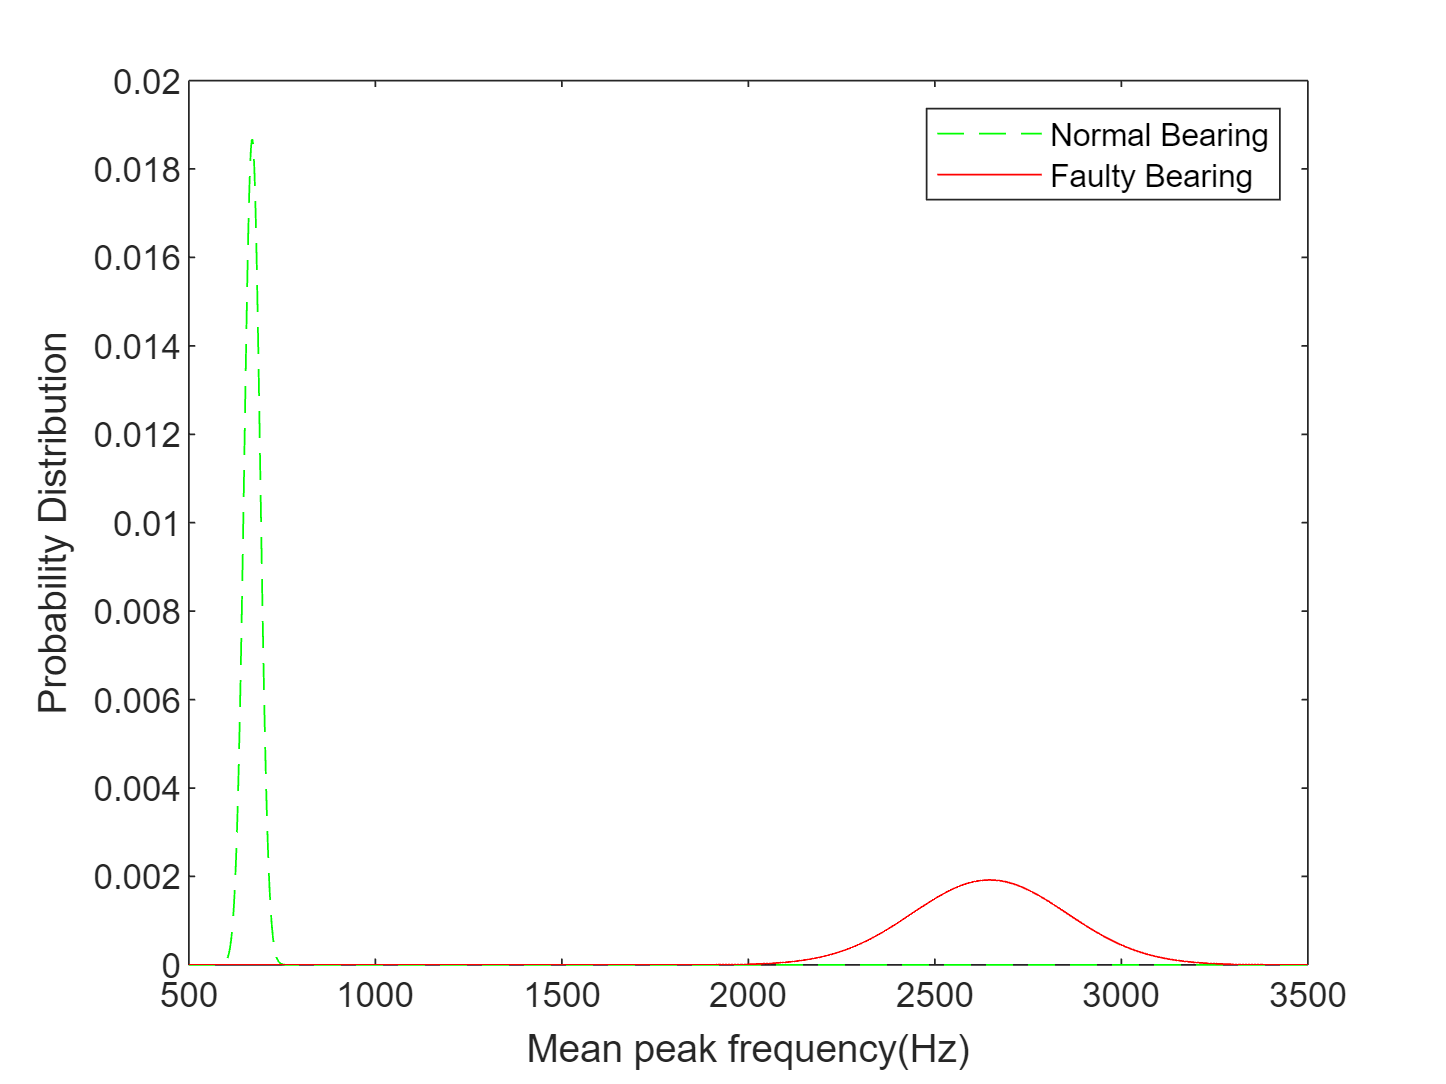

plot(pFreq,pNormal,'g--',pFreq,pFaulty,'r');
xlabel('Mean peak frequency(Hz)');
ylabel('Probability Distribution');
legend('Normal Bearing','Faulty Bearing');

Based on this plot, set the threshold for the mean peak frequency to 2000Hz to distinguish normal bearings from faulty bearings as well as maximize the use of the bearings.

threshold = 2000;

Calculate sampling time and convert its unit to seconds.

samplingTime = 60*(expTime(2)-expTime(1));                  % unit: seconds
tsFeature = iddata(meanPeakFreq(1:tStart),[],samplingTime);

Plot the initial 200 mean peak frequency data.

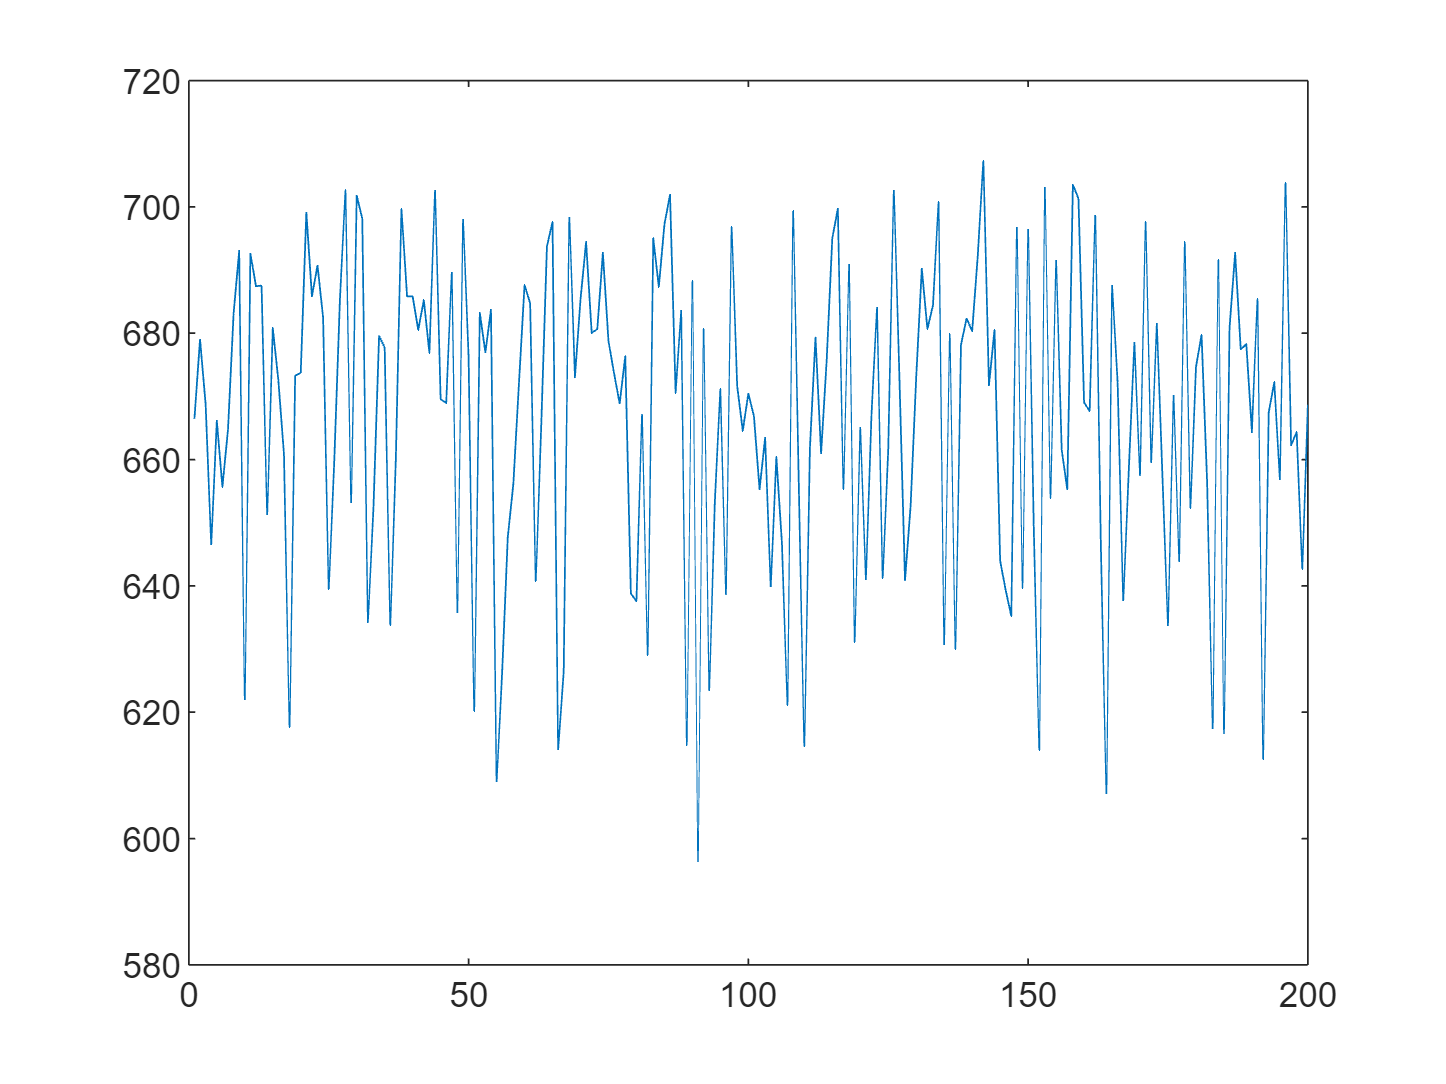

plot(tsFeature.y)

The plot shows that the initial data is a combination of constant level and noise. This is expected as initially the bearing is healthy and the mean peak frequency is not expected to change significantly

Identify a second-order state-space model using the first 200 data points. Obtain the model in canonical form and specify the sampling time.

past_sys = ssest(tsFeature,2,'Ts',samplingTime,'Form','canonical')

past_sys =
  식별된 이산시간 상태공간 모델:
    x(t+Ts) = A x(t) + K e(t)
       y(t) = C x(t) + e(t)
 
  A = 
           x1      x2
   x1       0       1
   x2  0.8496  0.1503
 
  C = 
       x1  x2
   y1   1   0
 
  K = 
             y1
   x1   0.03413
   x2  -0.02907
 
샘플 시간: 600 seconds

파라미터화:
   다음 인덱스를 포함하는 CANONICAL 형식입니다. 2
   외란 성분: 추정
   자유 계수의 개수: 4
   파라미터 및 그 불확실성을 얻으려면 "idssdata", "getpvec", "getcov"를 사용하십시오.

상태:                                              
시간 영역 데이터 "tsFeature"에 대해 SSEST을(를) 사용하여 추정되었습니다.
추정 데이터에 피팅: 0.1531%(예측 중점)                       
FPE: 641.6, MSE: 604.2                           
 
모델 속성


The initial estimated dynamic model has a low goodness of fit. The goodness of fit metric is the normalized root mean square error (NRMSE), calculated as


$$NRMSE = 1 - \frac{\Vert x_{true} - x_{pred} \Vert}{\Vert x_{true} - mean(x_{true}) \Vert}$$


where $x_{true}$ is the true value, $x_{pred}$ is the predicted value.

When the estimation data is a combination of constant level and noise, $x_{pred}\approx mean(x_{true})$, giving a NRMSE close to 0. To validate the model, plot the autocorrelation of residuals. 

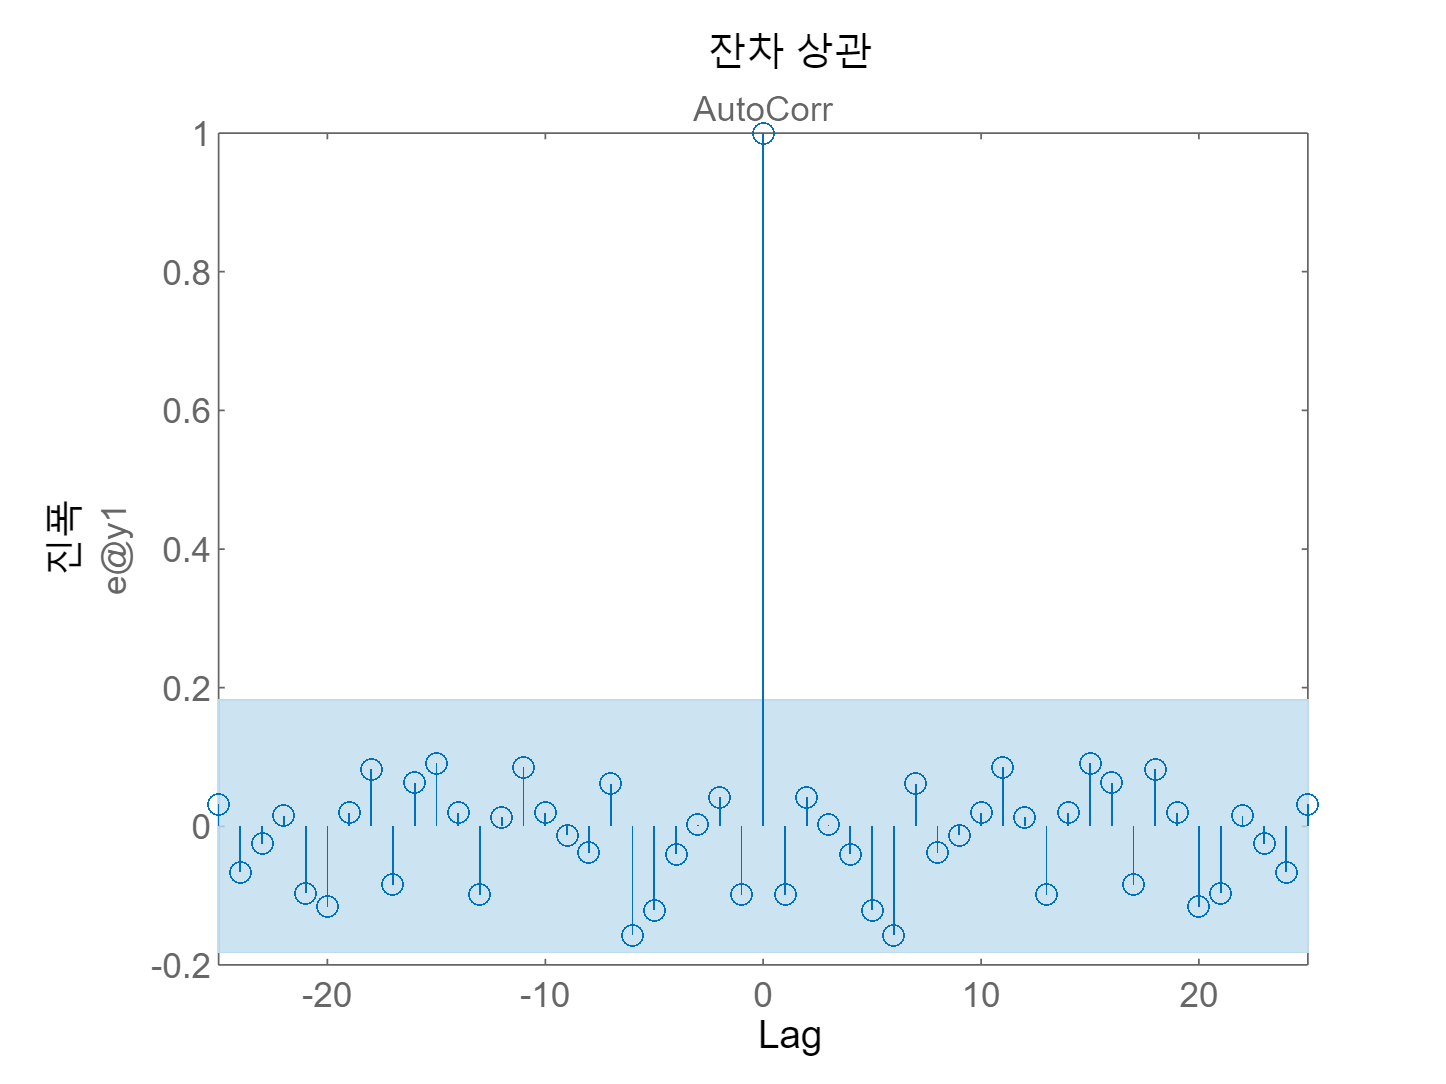

resid(tsFeature,past_sys)

As seen, the residuals are uncorrelated and the generated model is valid.

Use the identified model `past_sys` to forecast mean peak frequency values and compute the standard deviation of the forecasted values.

[yF,~,~,yFSD] = forecast(past_sys,tsFeature,forecastLen);

Plot the forecasted values and confidence intervals.

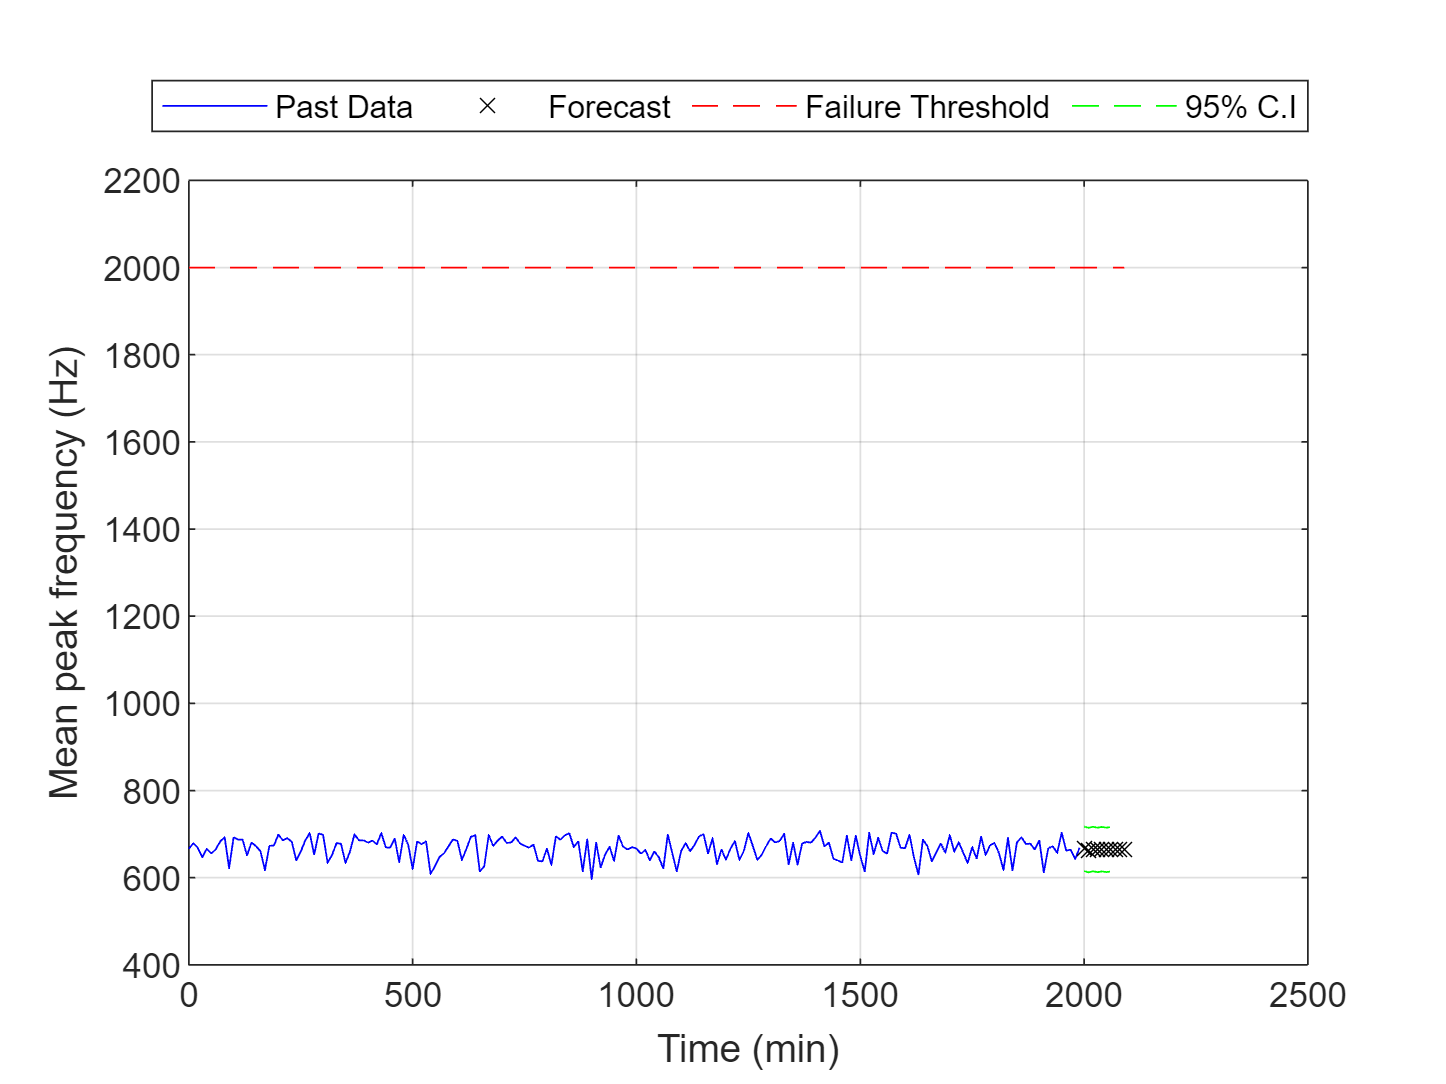

tHistory = expTime(1:tStart);
forecastTimeIdx = (tStart+1):(tStart+forecastLen);
tForecast = expTime(forecastTimeIdx);

% Plot historical data, forecast value and 95% confidence interval.
plot(tHistory,meanPeakFreq(1:tStart),'b',...
     tForecast,yF.OutputData,'kx',...
     [tHistory; tForecast], threshold*ones(1,length(tHistory)+forecastLen), 'r--',...
     tForecast,yF.OutputData+1.96*yFSD,'g--',...
     tForecast,yF.OutputData-1.96*yFSD,'g--');

ylim([400, 1.1*threshold]);
ylabel('Mean peak frequency (Hz)');
xlabel('Time (min)');
legend({'Past Data', 'Forecast', 'Failure Threshold', '95% C.I'},...
    'Location','northoutside','Orientation','horizontal');
grid on;

The plot shows that the forecasted values of the mean peak frequency are well below the threshold.

Now update model parameters as new data comes in, and re-estimate the forecasted values. Also create an alarm to check if the signals or the forecasted value exceed the failure threshold.

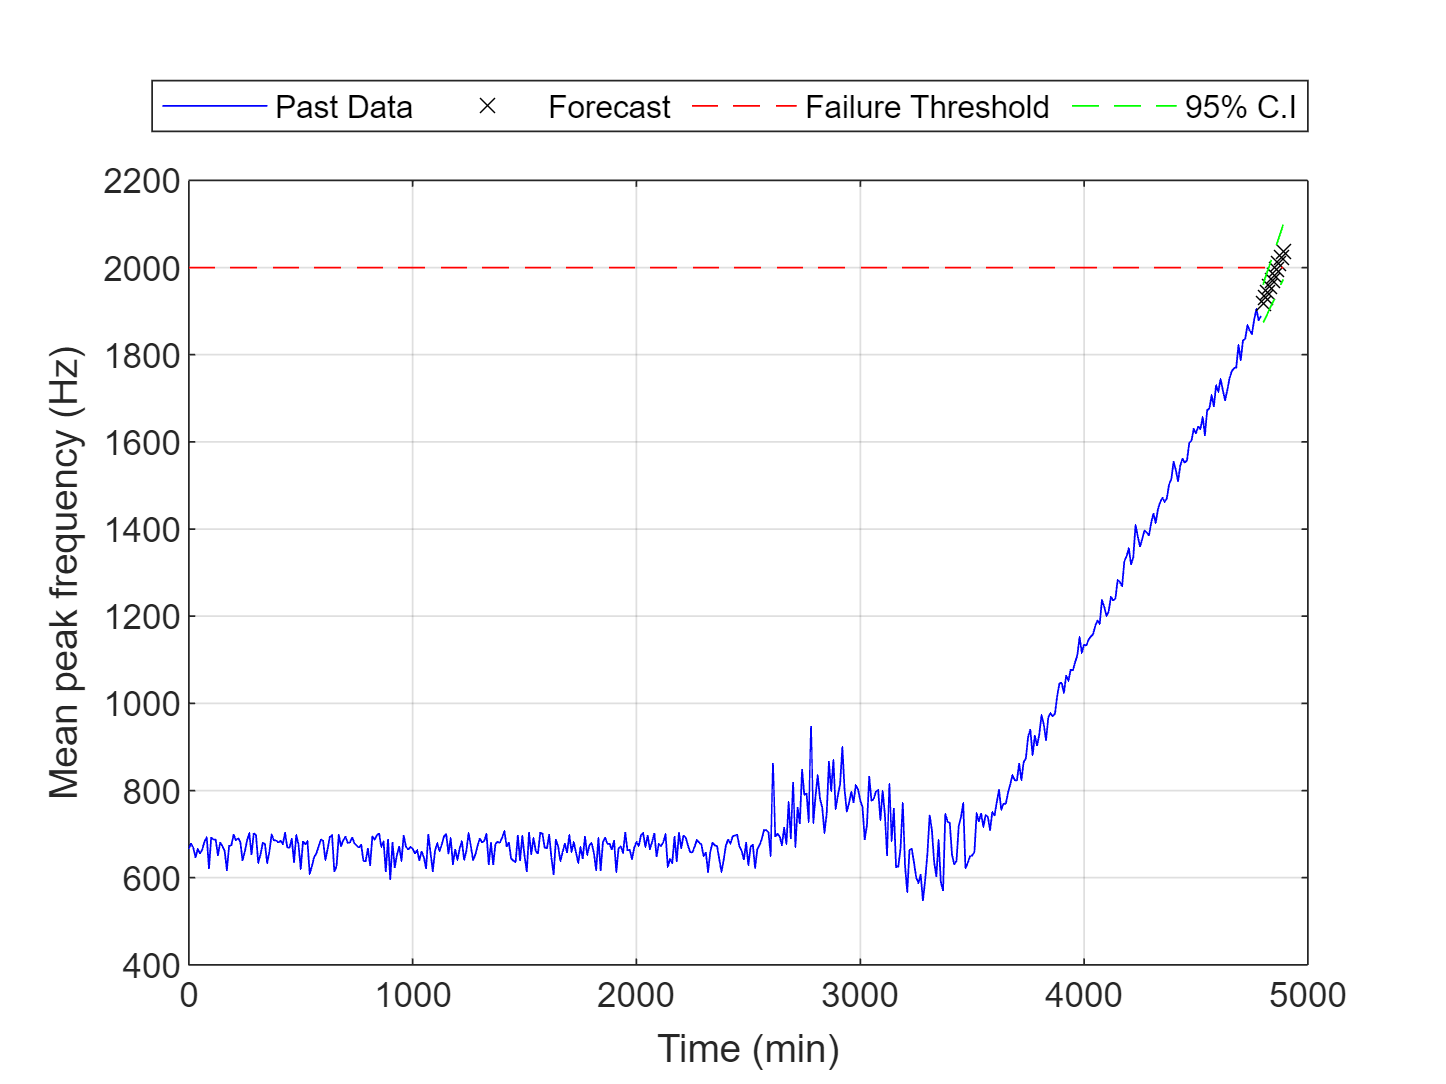

Estimated to hit failure threshold in 80 minutes from now.


for tCur = tStart:batchSize:numSamples
    %  latest features into iddata object.
    tsFeature = iddata(meanPeakFreq((tCur-timeSeg+1):tCur),[],samplingTime);
    
    % Update system parameters when new data comes in. Use previous model
    % parameters as initial guesses.
    sys = ssest(tsFeature,past_sys);
    past_sys = sys;
    
    % Forecast the output of the updated state-space model. Also compute
    % the standard deviation of the forecasted output.
    [yF,~,~,yFSD]  = forecast(sys, tsFeature, forecastLen);
    
    % Find the time corresponding to historical data and forecasted values.
    tHistory = expTime(1:tCur);
    forecastTimeIdx = (tCur+1):(tCur+forecastLen);
    tForecast = expTime(forecastTimeIdx);
    
    % Plot historical data, forecasted mean peak frequency value and 95%
    % confidence interval.
    plot(tHistory,meanPeakFreq(1:tCur),'b',...
              tForecast,yF.OutputData,'kx',...
              [tHistory; tForecast], threshold*ones(1,length(tHistory)+forecastLen), 'r--',...
              tForecast,yF.OutputData+1.96*yFSD,'g--',...
              tForecast,yF.OutputData-1.96*yFSD,'g--');

    ylim([400, 1.1*threshold]);
    ylabel('Mean peak frequency (Hz)');
    xlabel('Time (min)');
    legend({'Past Data', 'Forecast', 'Failure Threshold', '95% C.I'},...
           'Location','northoutside','Orientation','horizontal');
    grid on;
    
    % Display an alarm when actual monitored variables or forecasted values exceed
    % failure threshold.
    if(any(meanPeakFreq(tCur-batchSize+1:tCur)>threshold))
        disp('Monitored variable exceeds failure threshold');
        break;
    elseif(any(yF.y>threshold))
        % Estimate the time when the system will reach failure threshold.
        tAlarm = tForecast(find(yF.y>threshold,1));
        disp(['Estimated to hit failure threshold in ' num2str(tAlarm-tHistory(end)) ' minutes from now.']);
        break;
    end
end

Examine the most recent time series model. 

sys

sys =
  식별된 이산시간 상태공간 모델:
    x(t+Ts) = A x(t) + K e(t)
       y(t) = C x(t) + e(t)
 
  A = 
           x1      x2
   x1       0       1
   x2  0.2624   0.746
 
  C = 
       x1  x2
   y1   1   0
 
  K = 
           y1
   x1  0.3902
   x2  0.3002
 
샘플 시간: 600 seconds

파라미터화:
   다음 인덱스를 포함하는 CANONICAL 형식입니다. 2
   외란 성분: 추정
   자유 계수의 개수: 4
   파라미터 및 그 불확실성을 얻으려면 "idssdata", "getpvec", "getcov"를 사용하십시오.

상태:                                              
시간 영역 데이터 "tsFeature"에 대해 SSEST을(를) 사용하여 추정되었습니다.
추정 데이터에 피팅: 92.53%(예측 중점)                        
FPE: 499.3, MSE: 442.7                           
 
모델 속성


The goodness of fit increases to above 90%, and the trend is correctly captured.

## Conclusions

This example shows how to extract features from measured data to perform condition monitoring and prognostics. Based on extracted features, dynamic models are generated, validated and used to forecast time of failures so that actions can be taken before actual failures happen.

*Copyright 1986-2018 The MathWorks, Inc.*